%% Task D: Find Force and Angle for Target Landing and Maximum Height
% This script determines the required force (F) and angle (theta) to make the rocket 
% land at x = 7.45 meters and reach a maximum height of y = 15 meters.
% Implements Newton's method for finding the roots of the system of equations.
% Includes visualization and error analysis.

%% Clear environment
clear all
close all
clc

%% Define initial parameters
% Initial conditions
v_init = 21;             % Initial velocity magnitude (m/s)
theta_init = 45;         % Initial guess for angle (degrees)
theta_guess = deg2rad(theta_init); % Convert to radians

% Simulation parameters
t_start = 0;             % Start time (s)
t_burn = 0.08;           % Burn time end (s)
t_end = 4;               % Simulation end time (s)
h = 0.01;                % Time step (s)
F_guess = 0.5;           % Initial guess for force (N)

% Target positions
target_x = 7.45;         % Target landing position (m)
target_y_max = 15;       % Target maximum height (m)

% Newton's method parameters
step_interp = 1;         % Step size for interpolation points
epsilon = 1e-5;          % Small value for derivative approximation
tol = 1e-9;              % Tolerance for convergence
max_iter = 30;           % Maximum number of iterations

% Initial values vector for functions
IV = [t_start, t_burn, t_end, h, v_init, step_interp, epsilon, 1, tol];

%% Part 1: Find optimal force and angle using Newton's method
fprintf('=== Part 1: Finding Force and Angle Values Using Newton''s Method ===\n');

=== Part 1: Finding Force and Angle Values Using Newton's Method ===



% Call Newton's method to find force and angle
[F_optimal, theta_optimal, iterations, jacobian_matrices] = newton_method(F_guess, theta_guess, IV);

% Convert optimal angle to degrees for display
theta_degrees = rad2deg(theta_optimal);

% Print results
fprintf('Optimal force: F = %.9f N\n', F_optimal);

Optimal force: F = -0.095682513 N


fprintf('Optimal angle: θ = %.9f degrees\n', theta_degrees);

Optimal angle: θ = 81.582579452 degrees


fprintf('Converged in %d iterations\n', iterations);

Converged in 7 iterations



%% Part 2: Verify results by simulating trajectory with optimal parameters
fprintf('\n=== Part 2: Verifying Results with Simulation ===\n');


=== Part 2: Verifying Results with Simulation ===



% Simulate rocket trajectory with optimal force and angle
[z, t] = simulate_rocket(t_start, t_burn, t_end, h, F_optimal, v_init, theta_optimal);

% Find landing point
[landing_idx, ~] = find_landing_index(z);
if landing_idx > 1
    landing_x = find_landing_position_interp(z, landing_idx, step_interp);
else
    landing_x = z(1, end);
end

% Find maximum height
[max_height, max_idx] = max(z(2,:));
max_height_interp = find_max_height_interp(z, max_idx, step_interp);

% Report verification results
fprintf('Simulated landing position: x = %.6f m (target: %.6f m)\n', landing_x, target_x);

Simulated landing position: x = 7.450000 m (target: 7.450000 m)


fprintf('Simulated maximum height: y = %.6f m (target: %.6f m)\n', max_height_interp, target_y_max);

Simulated maximum height: y = 15.000000 m (target: 15.000000 m)


fprintf('Absolute errors: Δx = %.6e m, Δy = %.6e m\n', ...
        abs(landing_x - target_x), abs(max_height_interp - target_y_max));

Absolute errors: Δx = 8.881784e-16 m, Δy = 1.776357e-15 m



%% Part 3: Sensitivity Analysis (Optional)
fprintf('\n=== Part 3: Sensitivity Analysis ===\n');


=== Part 3: Sensitivity Analysis ===



% Define perturbation percentage
perturbation = 0.01; % 1%

% Initialize arrays for sensitivity analysis
perturbed_params = cell(4,1);
perturbed_values = zeros(4,2); % [landing_x, max_height]

% 1. Increase F by 1%
F_plus = F_optimal * (1 + perturbation);
[z_F_plus, ~] = simulate_rocket(t_start, t_burn, t_end, h, F_plus, v_init, theta_optimal);
[idx_F_plus, ~] = find_landing_index(z_F_plus);
landing_F_plus = find_landing_position_interp(z_F_plus, idx_F_plus, step_interp);
[~, max_idx_F_plus] = max(z_F_plus(2,:));
max_height_F_plus = find_max_height_interp(z_F_plus, max_idx_F_plus, step_interp);
perturbed_params{1} = 'F increased by 1%';
perturbed_values(1,:) = [landing_F_plus, max_height_F_plus];

% 2. Decrease F by 1%
F_minus = F_optimal * (1 - perturbation);
[z_F_minus, ~] = simulate_rocket(t_start, t_burn, t_end, h, F_minus, v_init, theta_optimal);
[idx_F_minus, ~] = find_landing_index(z_F_minus);
landing_F_minus = find_landing_position_interp(z_F_minus, idx_F_minus, step_interp);
[~, max_idx_F_minus] = max(z_F_minus(2,:));
max_height_F_minus = find_max_height_interp(z_F_minus, max_idx_F_minus, step_interp);
perturbed_params{2} = 'F decreased by 1%';
perturbed_values(2,:) = [landing_F_minus, max_height_F_minus];

% 3. Increase theta by 1%
theta_plus = theta_optimal * (1 + perturbation);
[z_theta_plus, ~] = simulate_rocket(t_start, t_burn, t_end, h, F_optimal, v_init, theta_plus);
[idx_theta_plus, ~] = find_landing_index(z_theta_plus);
landing_theta_plus = find_landing_position_interp(z_theta_plus, idx_theta_plus, step_interp);
[~, max_idx_theta_plus] = max(z_theta_plus(2,:));
max_height_theta_plus = find_max_height_interp(z_theta_plus, max_idx_theta_plus, step_interp);
perturbed_params{3} = 'θ increased by 1%';
perturbed_values(3,:) = [landing_theta_plus, max_height_theta_plus];

% 4. Decrease theta by 1%
theta_minus = theta_optimal * (1 - perturbation);
[z_theta_minus, ~] = simulate_rocket(t_start, t_burn, t_end, h, F_optimal, v_init, theta_minus);
[idx_theta_minus, ~] = find_landing_index(z_theta_minus);
landing_theta_minus = find_landing_position_interp(z_theta_minus, idx_theta_minus, step_interp);
[~, max_idx_theta_minus] = max(z_theta_minus(2,:));
max_height_theta_minus = find_max_height_interp(z_theta_minus, max_idx_theta_minus, step_interp);
perturbed_params{4} = 'θ decreased by 1%';
perturbed_values(4,:) = [landing_theta_minus, max_height_theta_minus];

% Print sensitivity analysis results
fprintf('Sensitivity Analysis Results:\n');

Sensitivity Analysis Results:


fprintf('Parameter            | Landing Position (m) | Maximum Height (m) | Δx (m)      | Δy (m)\n');

Parameter            | Landing Position (m) | Maximum Height (m) | Δx (m)      | Δy (m)


fprintf('---------------------|---------------------|-------------------|------------|------------\n');

---------------------|---------------------|-------------------|------------|------------


fprintf('Optimal values       | %.6f             | %.6f           | -          | -\n', landing_x, max_height_interp);

Optimal values       | 7.450000             | 15.000000           | -          | -


for i = 1:4
    fprintf('%s | %.6f             | %.6f           | %.6e | %.6e\n', ...
            perturbed_params{i}, perturbed_values(i,1), perturbed_values(i,2), ...
            perturbed_values(i,1) - landing_x, perturbed_values(i,2) - max_height_interp);
end

F increased by 1% | 7.449270             | 14.998308           | -7.299541e-04 | -1.691830e-03
F decreased by 1% | 7.450730             | 15.001692           | 7.299706e-04 | 1.691896e-03
θ increased by 1% | 6.755277             | 15.057902           | -6.947229e-01 | 5.790174e-02
θ decreased by 1% | 8.136538             | 14.936463           | 6.865376e-01 | -6.353675e-02


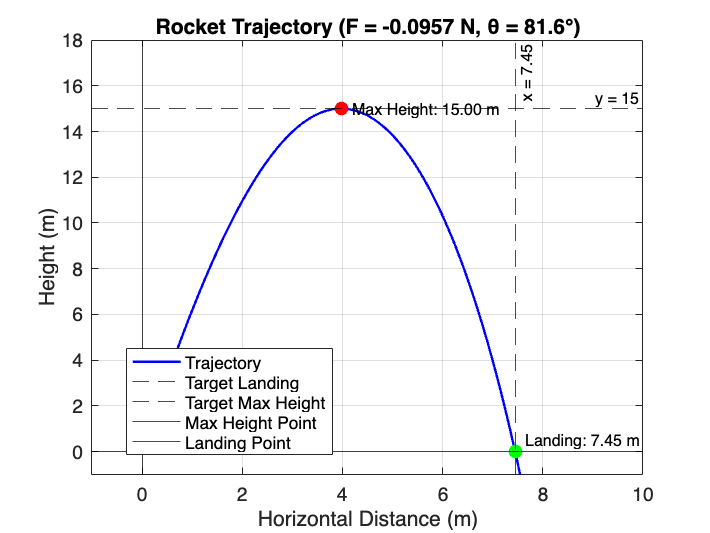


%% Visualize results
figure;
plot(z(1,:), z(2,:), 'b-', 'LineWidth', 1.5); 
hold on;
xline(target_x, '--k', ['x = ', num2str(target_x)]);
yline(target_y_max, '--k', ['y = ', num2str(target_y_max)]);
xline(0, 'k-');
yline(0, 'k-');
xlim([-1, 10]);
ylim([-1, 18]);

% Mark the maximum height point
[~, max_idx] = max(z(2,:));
plot(z(1, max_idx), z(2, max_idx), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(z(1, max_idx)+0.2, z(2, max_idx), sprintf('Max Height: %.2f m', max_height_interp), 'FontSize', 10);

% Mark the landing point
[landing_idx, ~] = find_landing_index(z);
plot(landing_x, 0, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
text(landing_x+0.2, 0.5, sprintf('Landing: %.2f m', landing_x), 'FontSize', 10);

% Add title and labels
title(sprintf('Rocket Trajectory (F = %.4f N, θ = %.1f°)', F_optimal, theta_degrees));
xlabel('Horizontal Distance (m)');
ylabel('Height (m)');
grid on;
legend('Trajectory', 'Target Landing', 'Target Max Height', 'Max Height Point', 'Landing Point', 'Location', 'best');
set(gca, 'FontSize', 12);


%% Helper Functions

function [F, theta, iterations, jacobian_matrices] = newton_method(F_guess, theta_guess, IV)
    % Newton's method implementation for finding optimal force and angle
    % Input:
    %   F_guess: Initial guess for force (N)
    %   theta_guess: Initial guess for angle (radians)
    %   IV: Initial values [t_start, t_burn, t_end, h, v_init, step, epsilon, flag, tol]
    % Output:
    %   F: Optimal force (N)
    %   theta: Optimal angle (radians)
    %   iterations: Number of iterations for convergence
    %   jacobian_matrices: Cell array of Jacobian matrices at each iteration

    % Extract parameters from IV
    t_start = IV(1); 
    t_burn = IV(2);
    t_end = IV(3);
    h = IV(4);
    v_init = IV(5);
    step = IV(6);
    epsilon = IV(7);
    tol = IV(9);
    
    % Initialize solution vector and correction
    R = [F_guess; theta_guess];
    delta = [0.01; 0.001];
    
    % Define target functions
    target_x = 7.45;  % Target landing position
    target_y_max = 15;  % Target maximum height
    
    % Create anonymous functions for the system
    func1 = @(F, theta) find_landing_position(F, h, theta, step, IV) - target_x;
    func2 = @(F, theta) find_max_height(F, h, theta, step, IV) - target_y_max;
    
    % Newton's method iterations
    iterations = 0;
    jacobian_matrices = cell(30, 1);  % Pre-allocate for up to 30 iterations
    
    while norm(delta) > tol && iterations < 30
        F_current = R(1);
        theta_current = R(2);
        
        % Evaluate functions at current point
        G = [func1(F_current, theta_current); 
             func2(F_current, theta_current)];
        
        % Compute Jacobian numerically
        J = [(func1(F_current + epsilon, theta_current) - func1(F_current, theta_current))/epsilon, ...
             (func1(F_current, theta_current + epsilon) - func1(F_current, theta_current))/epsilon;
             (func2(F_current + epsilon, theta_current) - func2(F_current, theta_current))/epsilon, ...
             (func2(F_current, theta_current + epsilon) - func2(F_current, theta_current))/epsilon];
        
        % Store Jacobian
        jacobian_matrices{iterations + 1} = J;
        
        % Solve for correction
        delta = J \ (-G);
        
        % Update solution
        R = R + delta;
        
        iterations = iterations + 1;
    end
    
    % Extract results
    F = R(1);
    theta = R(2);
    
    % Trim unused cells
    jacobian_matrices = jacobian_matrices(1:iterations);
end

function y_max = find_max_height(F, h, theta, step, data)
    % Find the maximum height of the rocket trajectory
    % Input:
    %   F: Force (N)
    %   h: Time step (s)
    %   theta: Angle (radians)
    %   step: Step size for interpolation
    %   data: Vector with [t_start, t_burn, t_end, v_init]
    % Output:
    %   y_max: Maximum height (m)
    
    % Extract parameters
    t_start = data(1);
    t_burn = data(2);
    t_end = data(3);
    v_init = data(5);
    
    % Simulate rocket trajectory
    [z, ~] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta);
    
    % Find index of maximum height
    [~, idx_max] = max(z(2,:));
    
    % Use quadratic interpolation to refine maximum height
    y_max = find_max_height_interp(z, idx_max, step);
end

function x_landing = find_landing_position(F, h, theta, step, data)
    % Find the landing position of the rocket
    % Input:
    %   F: Force (N)
    %   h: Time step (s)
    %   theta: Angle (radians)
    %   step: Step size for interpolation
    %   data: Vector with [t_start, t_burn, t_end, v_init]
    % Output:
    %   x_landing: Landing position (m)
    
    % Extract parameters
    t_start = data(1);
    t_burn = data(2);
    t_end = data(3);
    v_init = data(5);
    
    % Simulate rocket trajectory
    [z, ~] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta);
    
    % Find landing index
    [idx_landing, ~] = find_landing_index(z);
    
    % Use linear interpolation to refine landing position
    x_landing = find_landing_position_interp(z, idx_landing, step);
end

function [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta)
    % Simulate rocket trajectory using Runge-Kutta method
    % Input:
    %   t_start: Start time (s)
    %   t_burn: Burn time end (s)
    %   t_end: End time (s)
    %   h: Time step (s)
    %   F: Force (N)
    %   v_init: Initial velocity magnitude (m/s)
    %   theta: Angle (radians)
    % Output:
    %   z: Solution matrix [x, y, vx, vy]
    %   t: Time values
    
    % Initial conditions
    x0 = 0;
    y0 = 0;
    [vx0, vy0] = decompose_velocity(v_init, theta);
    
    % Phase 1: With thrust (t_start to t_burn)
    [z1, t1] = runge_kutta(t_start, t_burn, h, F, x0, y0, vx0, vy0, theta);
    
    % Phase 2: No thrust (t_burn to t_end)
    [z2, t2] = runge_kutta(t_burn, t_end, h, 0, z1(1,end), z1(2,end), z1(3,end), z1(4,end), theta);
    
    % Combine results
    z = [z1, z2(:,2:end)];
    t = [t1, t2(2:end)];
end

function [z, t] = runge_kutta(t_start, t_end, h, F, x0, y0, vx0, vy0, theta)
    % Runge-Kutta 4th order method for solving rocket differential equations
    % Input:
    %   t_start: Start time (s)
    %   t_end: End time (s)
    %   h: Time step (s)
    %   F: Force (N)
    %   x0, y0: Initial positions (m)
    %   vx0, vy0: Initial velocities (m/s)
    %   theta: Angle (radians)
    % Output:
    %   z: Solution matrix [x, y, vx, vy]
    %   t: Time values
    
    % Generate time values
    t = t_start:h:t_end;
    N = length(t);
    
    % Initialize solution matrix [x, y, vx, vy]
    z = zeros(4, N);
    z(:, 1) = [x0; y0; vx0; vy0];
    
    % Runge-Kutta integration
    for i = 1:N-1
        t_current = t(i);
        z_current = z(:, i);
        
        % Four steps of RK4 method
        k1 = rocket_ode(t_current, z_current, F, theta);
        k2 = rocket_ode(t_current + h/2, z_current + (h/2)*k1, F, theta);
        k3 = rocket_ode(t_current + h/2, z_current + (h/2)*k2, F, theta);
        k4 = rocket_ode(t_current + h, z_current + h*k3, F, theta);
        
        % Update solution
        z(:, i+1) = z_current + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end

function dzdt = rocket_ode(t, z, F_val, theta_init)
    % Rocket differential equations
    % Input:
    %   t: Current time (s)
    %   z: Current state [x, y, vx, vy]
    %   F_val: Force (N)
    %   theta_init: Initial angle (radians)
    % Output:
    %   dzdt: Derivatives [dx/dt, dy/dt, dvx/dt, dvy/dt]
    
    % Extract state variables
    x = z(1);      % Position x
    y = z(2);      % Position y
    vx = z(3);     % Velocity x
    vy = z(4);     % Velocity y
    
    % Physical parameters
    g = 9.82;      % Gravity (m/s²)
    m0 = 0.05;     % Initial mass (kg)
    k_x = 0.001;   % Air resistance coefficient x
    k_y = 0.001;   % Air resistance coefficient y
    k = 0.08;      % Mass flow rate (kg/s)
    
    % Calculate current mass
    if t <= 0.08
        m = m0 - k*t;
    else
        m = m0 - k*0.08;  % Mass remaining after burn time
    end
    
    % Calculate thrust force
    if t <= 0.08
        F = F_val;
    else
        F = 0;  % No thrust after burn time
    end
    
    % Calculate angle
    if t <= 0
        phi = theta_init;
    else
        phi = atan2(vy, vx);  % Using atan2 for correct quadrant
    end
    
    % Calculate speed
    V = sqrt(vx^2 + vy^2);
    
    % Differential equations
    dzdt = zeros(4, 1);
    dzdt(1) = vx;
    dzdt(2) = vy;
    dzdt(3) = (F*cos(phi) - k_x*vx*V)/m;
    dzdt(4) = (F*sin(phi) - k_y*vy*V)/m - g;
end

function [vx, vy] = decompose_velocity(v, theta)
    % Decompose velocity into x and y components
    % Input:
    %   v: Velocity magnitude (m/s)
    %   theta: Angle (radians)
    % Output:
    %   vx, vy: Velocity components (m/s)
    
    vx = v*cos(theta);
    vy = v*sin(theta);
end

function [idx, y_val] = find_landing_index(z)
    % Find index where the rocket crosses y=0 (landing)
    % Input:
    %   z: Solution matrix [x, y, vx, vy]
    % Output:
    %   idx: Index of landing point
    %   y_val: Height at index point
    
    y = z(2,:);
    idx = 0;
    
    for i = 2:length(y)
        if y(i-1) > 0 && y(i) <= 0
            idx = i;
            y_val = y(i);
            break;
        end
    end
    
    % If no landing found, return end of trajectory
    if idx == 0
        idx = length(y);
        y_val = y(end);
    end
end

function x_landing = find_landing_position_interp(z, idx_landing, step)
    % Find landing position using linear interpolation
    % Input:
    %   z: Solution matrix [x, y, vx, vy]
    %   idx_landing: Index of landing point
    %   step: Step size for interpolation
    % Output:
    %   x_landing: Interpolated landing position (m)
    
    % Get positions
    x_pos = z(1,:);
    y_pos = z(2,:);
    
    % Ensure valid landing index
    if idx_landing <= 1
        x_landing = x_pos(1);
        return;
    end
    
    % Get pre-landing index
    pre_idx = idx_landing - 1;
    
    % Get points for interpolation
    x1 = x_pos(pre_idx);
    y1 = y_pos(pre_idx);
    x2 = x_pos(idx_landing);
    y2 = y_pos(idx_landing);
    
    % Linear interpolation: y = mx + b
    m = (y2 - y1) / (x2 - x1);
    b = y1 - m*x1;
    
    % Find x when y = 0: 0 = mx + b => x = -b/m
    x_landing = -b / m;
end

function y_max = find_max_height_interp(z, idx_max, step)
    % Find maximum height using quadratic interpolation
    % Input:
    %   z: Solution matrix [x, y, vx, vy]
    %   idx_max: Index of maximum height
    %   step: Step size for interpolation
    % Output:
    %   y_max: Interpolated maximum height (m)
    
    % Get positions
    y_pos = z(2,:);
    
    % Determine interpolation points based on step size
    if idx_max > step && idx_max < length(y_pos) - step
        idx_range = [idx_max-step, idx_max, idx_max+step];
    else
        if idx_max <= step
            idx_range = [1, 1+step, 1+2*step];
        else  % idx_max is near the end
            idx_range = [length(y_pos)-2*step, length(y_pos)-step, length(y_pos)];
        end
    end
    
    % Get time values (use indices as time proxy)
    t_vals = idx_range;
    y_vals = y_pos(idx_range);
    
    % Perform quadratic interpolation to find maximum
    % Set up the matrix equation for polynomial coefficients
    A = [t_vals(1)^2, t_vals(1), 1;
         t_vals(2)^2, t_vals(2), 1;
         t_vals(3)^2, t_vals(3), 1];
    
    b = y_vals(:);
    
    % Solve for coefficients
    coeffs = A \ b;
    a = coeffs(1);
    b = coeffs(2);
    c = coeffs(3);
    
    % For a parabola y = ax^2 + bx + c
    % The maximum/minimum occurs at x = -b/(2a)
    t_max = -b / (2*a);
    
    % Calculate the corresponding y-value (maximum height)
    y_max = a*t_max^2 + b*t_max + c;
end